clc
clear
clf
load fisheriris.mat;


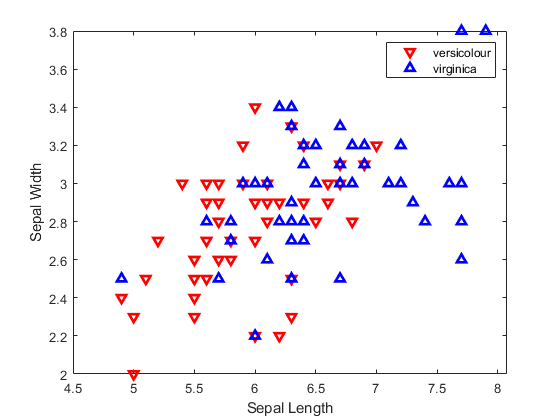

sepallength = meas(51:end, 1);
sepalwidth = meas(51:end,2);
group = species(51:end);

h = gscatter(sepallength, sepalwidth, group, 'rb', 'v^',[],'off'); set(h, 'LineWidth', 2)
xlabel('Sepal Length'); ylabel('Sepal Width'); legend('versicolour', 'virginica');

Apply LDA

mdl = fitcdiscr([sepallength sepalwidth], group, 'discrimtype', 'linear');


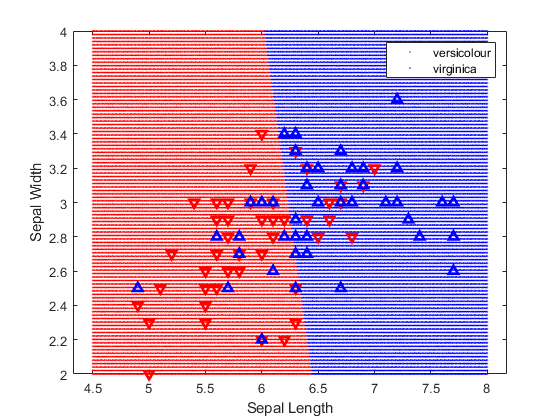

[L, W] = meshgrid(linspace(4.5, 8, 500), linspace(2,4,100)); ...
L = L(:);
W = W(:);
pred = mdl.predict([L W]);
h = gscatter(L, W, pred, 'rb', '.', 1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
hold on; 
h = gscatter(sepallength, sepalwidth, group, 'rb', 'v^',[],'off'); set(h, 'LineWidth', 2)
xlabel('Sepal Length'); ylabel('Sepal Width'); legend('versicolour', 'virginica'); hold off;

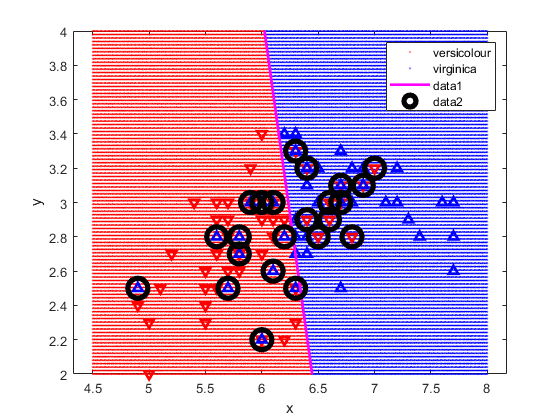

hold on;
A = mdl.Coeffs(1,2).Linear;
B = mdl.Coeffs(1,2).Const;
h = ezplot(@(x,y) [x y]*A + B, [4.5 8 2 4]); title('');
set(h, 'Color', 'm', 'LineWidth', 2);
hold off;
pred = mdl.predict([sepallength sepalwidth]);
Ibad = ~strcmp(pred, group);
hold on; 
plot(sepallength(Ibad), sepalwidth(Ibad), 'ko', 'LineWidth', 4, 'MarkerSize', 15);
hold off;

misclassificationrate = sum(Ibad) / numel(group);

## Confusion matrix

[confusionmatrix, matrixlabels] = confusionmat(group, pred);

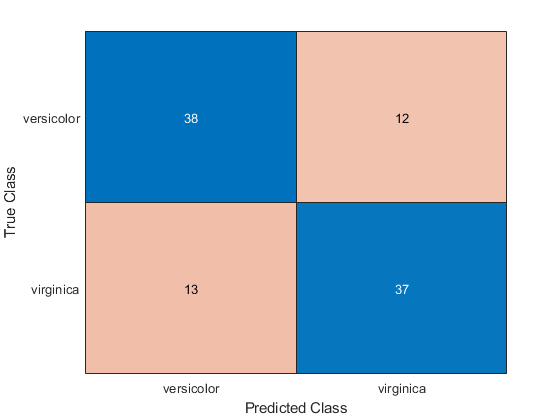

cm = confusionchart(group, pred);

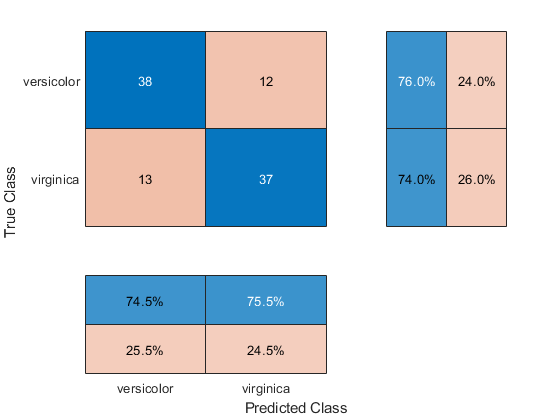

cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

## Multiple Groups

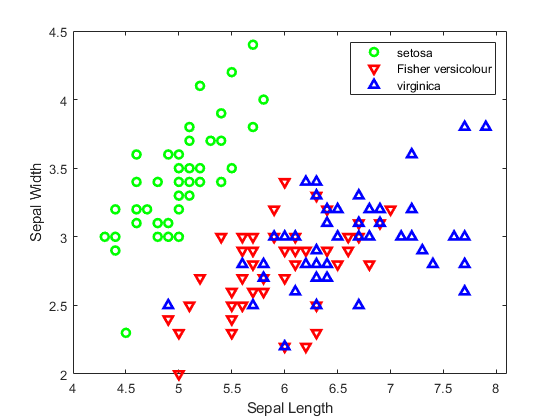

sepallength = meas(:,1);
sepalwidth = meas(:,2);
group = species(:);
h = gscatter(sepallength, sepalwidth, group, 'grb', 'ov^',[],'off'); set(h, 'LineWidth', 2)
xlabel('Sepal Length'); ylabel('Sepal Width'); legend('setosa','Fisher versicolour', 'virginica');

Apply LDA

mdl = fitcdiscr([sepallength sepalwidth], group, 'discrimtype', 'linear');


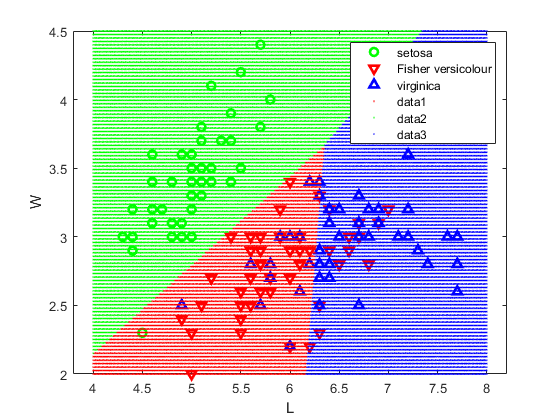

[L, W] = meshgrid(linspace(4, 8, 500), linspace(2,4.5,100)); ...
L = L(:);
W = W(:);
pred = mdl.predict([L W]);
hold on;
h = gscatter(L, W, pred, 'rgb', '.', 1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
hold off;

% 
% A = mdl.Coeffs(1,2).Linear;
% B = mdl.Coeffs(1,2).Const;
% h = ezplot(@(x,y) [x y]*A + B, [4.5 8 2 4]); title('');
% set(h, 'Color', 'm', 'LineWidth', 2);
% hold off;
pred = mdl.predict([sepallength sepalwidth]);
Igood = strcmp(pred, group);
accuracy = nnz(Igood) / numel(group);


## Confusion matrix

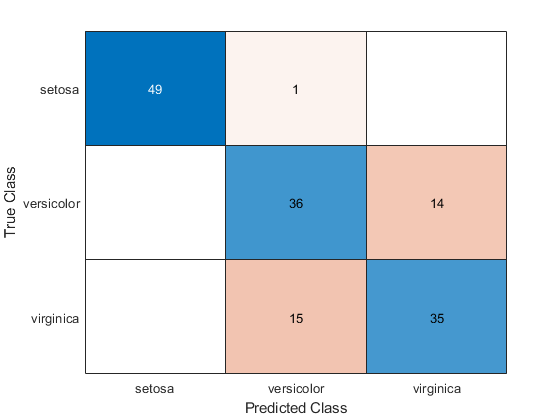

confusionchart(group, pred);